clc;
clear all;

% Choose modulation order and format
MOD_ORDER = 16;

MODULATION_FORMAT = 'QAM';

NUM_SYMBOLS_PER_CARRIER = 1e4;

NUM_SUBCARRIERS = 31;

CYCLIC_PREFIX_LENGTH = 1/8; % Given as a ratio of symbol length

OFDM_SYMBOL_LENGTH = ((2+2*NUM_SUBCARRIERS))*(1+CYCLIC_PREFIX_LENGTH);

assert(mod(OFDM_SYMBOL_LENGTH,1) == 0);

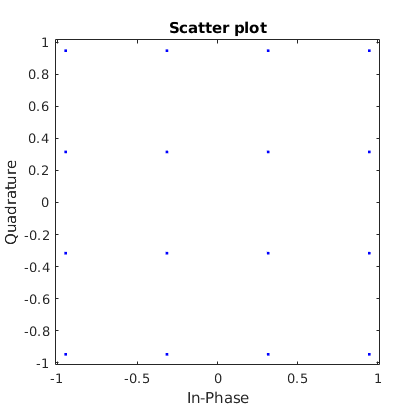

% Create QAM modulated signal, given number of symbols we want to generate

[modulated_signal, symbol_stream] = generateRandModSignal(NUM_SYMBOLS_PER_CARRIER, MOD_ORDER, NUM_SUBCARRIERS, MODULATION_FORMAT);
scatterplot(modulated_signal(:))

ofdm_signal = convertToOFDMSignal(modulated_signal, CYCLIC_PREFIX_LENGTH);
ofdm_signal = awgn(ofdm_signal,15,'measured');

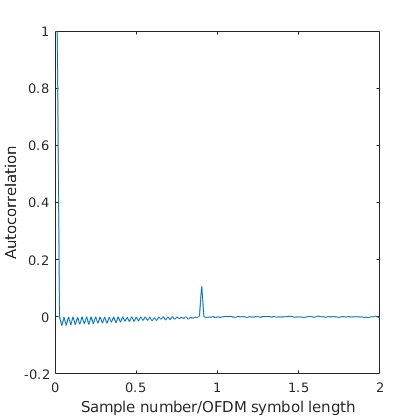

num_x_points = 301;
x_points = (1.0:1.0:num_x_points)/OFDM_SYMBOL_LENGTH;
% plot(ofdm_signal);
plot(x_points, autocorrelation(ofdm_signal, 300));
xlim([0,2]);
ylabel('Autocorrelation');
xlabel('Sample number/OFDM symbol length');

filename = strcat('OFDM_autocorrelation_', timestampString());
saveas(gcf, filename, 'epsc')

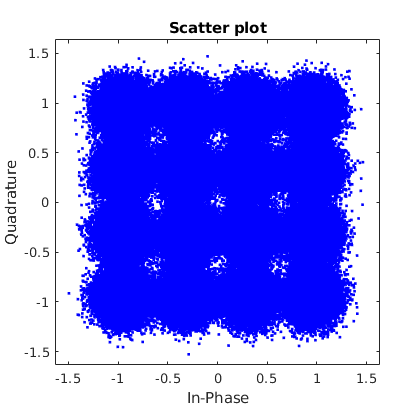

extracted_modulated_signal = convertFromOFDMSignal(ofdm_signal, NUM_SUBCARRIERS, CYCLIC_PREFIX_LENGTH);
scatterplot(extracted_modulated_signal(:))

extracted_stream = demodSignal(extracted_modulated_signal, MOD_ORDER, MODULATION_FORMAT);
[num_bit_errors, bit_error_rate, num_symbol_errors, symbol_error_rate] = calculateErrorRates(extracted_stream, symbol_stream);